A = [1.46337, -0.463369; 1, 0];
B = [1; 0];
C = [0.701522, 0.543461];
D = 0;
w = 1/1e15;

## 10 Iterations

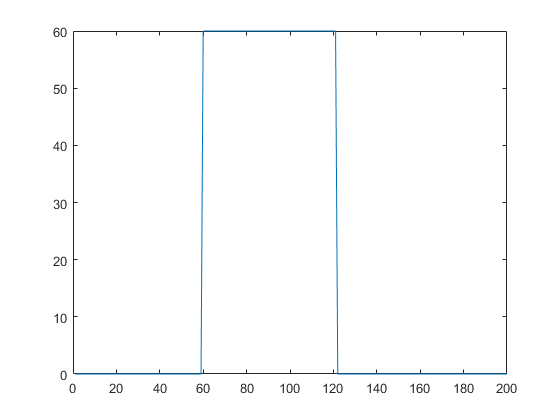

%
N = 200;

reference = zeros(N, 1);

G = zeros(N,N);
for row =  1:N 
    for col = 1:row
        G(row,col) = C*(A^(row-col))*B;
    end 
end

for i = 1:N
    if (i < 60) || (i > 121)
        reference(i, 1) = 0;
    else
        reference(i, 1) = 60;
    end
end

Iterations_10 = 10;

u_10 = zeros(N, Iterations_10+1);
e_10 = zeros(N, Iterations_10);
Y_10 = zeros(1, Iterations_10);
error_norm_10 = zeros(Iterations_10);
y_10 = zeros(N, Iterations_10);

for n = 1:Iterations_10
    e_10(:, n) = reference(:, 1) - G*u_10(:, n);
    Y_10(n) = ((norm(G'*e_10(:, n)))^2)/(w + (norm(G*G'*e_10(:, n)))^2);
    u_10(:, n+1) = u_10(:, n) + Y_10(n)*G'*e_10(:, n);
    error_norm_10(n) = norm(e_10(:, n));
    y_10(:, n) = G*u_10(:, n);
end

figure(1);
plot((1:200), reference);

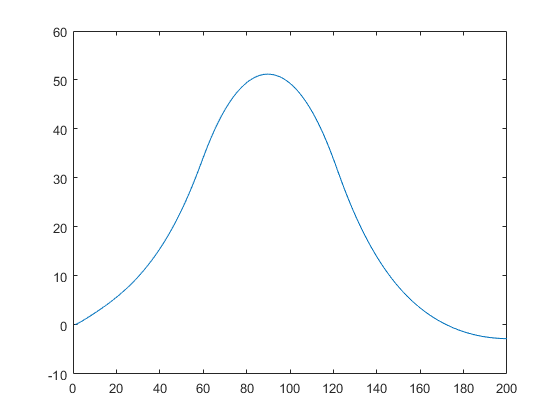

figure(2);
plot((1:200), y_10(:, Iterations_10));

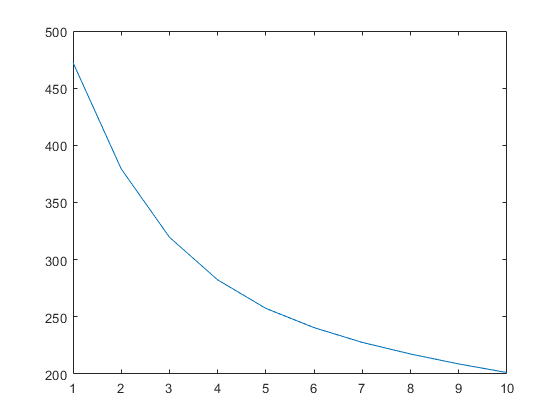

figure(3);
plot((1:Iterations_10), error_norm_10(:, 1));

%}

## 50 Iterations

%
N = 200;

reference = zeros(N, 1);

G = zeros(N,N);
for row =  1:N 
    for col = 1:row
        G(row,col) = C*(A^(row-col))*B;
    end 
end

for i = 1:N
    if (i < 60) || (i > 121)
        reference(i, 1) = 0;
    else
        reference(i, 1) = 60;
    end
end

Iterations_50 = 50;

u_50 = zeros(N, Iterations_50+1);
e_50 = zeros(N, Iterations_50);
Y_50 = zeros(1, Iterations_50);
error_norm_50 = zeros(Iterations_50);
y_50 = zeros(N, Iterations_50);

for n = 1:Iterations_50
    e_50(:, n) = reference(:, 1) - G*u_50(:, n);
    Y_50(n) = ((norm(G'*e_50(:, n)))^2)/(w + (norm(G*G'*e_50(:, n)))^2);
    u_50(:, n+1) = u_50(:, n) + Y_50(n)*G'*e_50(:, n);
    error_norm_50(n) = norm(e_50(:, n));
    y_50(:, n) = G*u_50(:, n);
end

figure(1);
plot((1:200), reference);

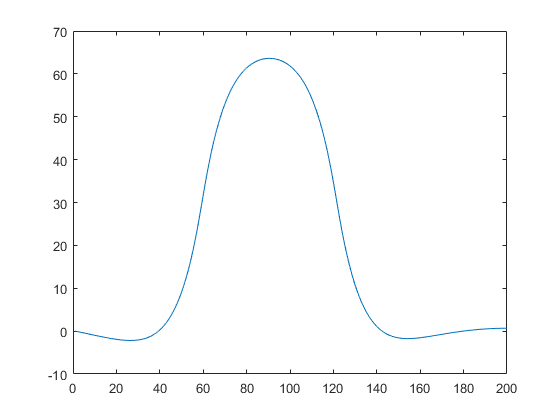

figure(2);
plot((1:200), y_50(:, Iterations_50));

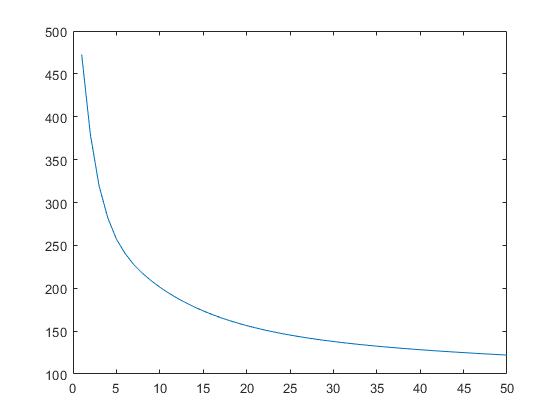

figure(3);
plot((1:Iterations_50), error_norm_50(:, 1));

%}

## 100 Iterations

%
N = 200;

reference = zeros(N, 1);

G = zeros(N,N);
for row =  1:N 
    for col = 1:row
        G(row,col) = C*(A^(row-col))*B;
    end 
end

for i = 1:N
    if (i < 60) || (i > 121)
        reference(i, 1) = 0;
    else
        reference(i, 1) = 60;
    end
end

Iterations_100 = 100;

u_100 = zeros(N, Iterations_100+1);
e_100 = zeros(N, Iterations_100);
Y_100 = zeros(1, Iterations_100);
error_norm_100 = zeros(Iterations_100);
y_100 = zeros(N, Iterations_100);

for n = 1:Iterations_100
    e_100(:, n) = reference(:, 1) - G*u_100(:, n);
    Y_100(n) = ((norm(G'*e_100(:, n)))^2)/(w + (norm(G*G'*e_100(:, n)))^2);
    u_100(:, n+1) = u_100(:, n) + Y_100(n)*G'*e_100(:, n);
    error_norm_100(n) = norm(e_100(:, n));
    y_100(:, n) = G*u_100(:, n);
end

figure(1);
plot((1:200), reference);

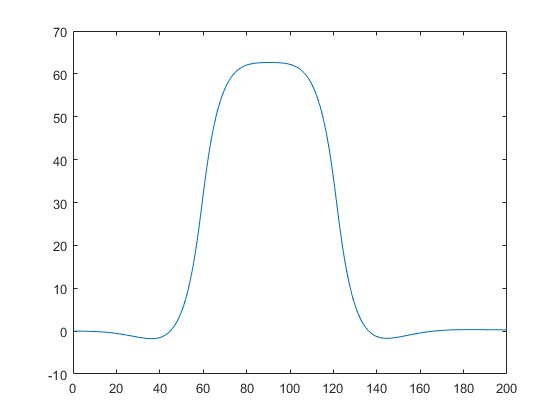

figure(2);
plot((1:200), y_100(:, Iterations_100));

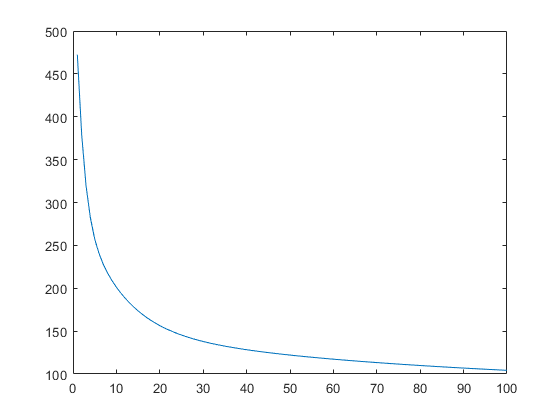

figure(3);
plot((1:Iterations_100), error_norm_100(:, 1));

%}

## 500 Iterations

%
N = 200;

reference = zeros(N, 1);

G = zeros(N,N);
for row =  1:N 
    for col = 1:row
        G(row,col) = C*(A^(row-col))*B;
    end 
end

for i = 1:N
    if (i < 60) || (i > 121)
        reference(i, 1) = 0;
    else
        reference(i, 1) = 60;
    end
end

Iterations_500 = 500;

u_500 = zeros(N, Iterations_500+1);
e_500 = zeros(N, Iterations_500);
Y_500 = zeros(1, Iterations_500);
error_norm_500 = zeros(Iterations_500);
y_500 = zeros(N, Iterations_500);

for n = 1:Iterations_500
    e_500(:, n) = reference(:, 1) - G*u_500(:, n);
    Y_500(n) = ((norm(G'*e_500(:, n)))^2)/(w + (norm(G*G'*e_500(:, n)))^2);
    u_500(:, n+1) = u_500(:, n) + Y_500(n)*G'*e_500(:, n);
    error_norm_500(n) = norm(e_500(:, n));
    y_500(:, n) = G*u_500(:, n);
end

figure(1);
plot((1:200), reference);

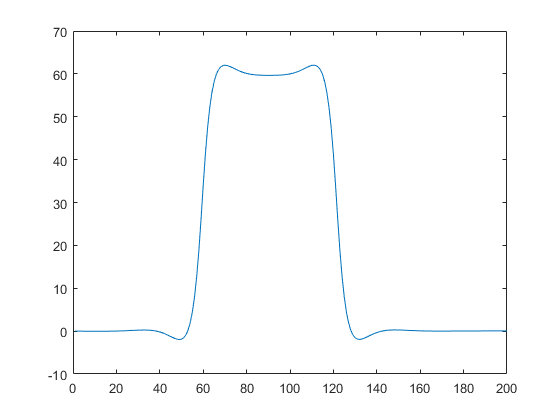

figure(2);
plot((1:200), y_500(:, Iterations_500));

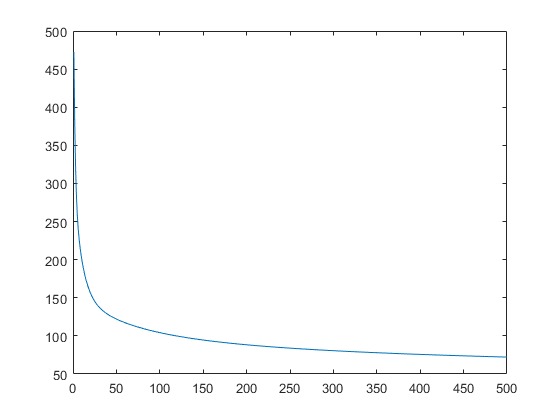

figure(3);
plot((1:Iterations_500), error_norm_500(:, 1));

%}

## 1000 Iterations

%
N = 200;

reference = zeros(N, 1);

G = zeros(N,N);
for row =  1:N 
    for col = 1:row
        G(row,col) = C*(A^(row-col))*B;
    end 
end

for i = 1:N
    if (i < 60) || (i > 121)
        reference(i, 1) = 0;
    else
        reference(i, 1) = 60;
    end
end

Iterations_1000 = 1000;

u_1000 = zeros(N, Iterations_1000+1);
e_1000 = zeros(N, Iterations_1000);
Y_1000 = zeros(1, Iterations_1000);
error_norm_1000 = zeros(Iterations_1000);
y_1000 = zeros(N, Iterations_1000);

for n = 1:Iterations_1000
    e_1000(:, n) = reference(:, 1) - G*u_1000(:, n);
    Y_1000(n) = ((norm(G'*e_1000(:, n)))^2)/(w + (norm(G*G'*e_1000(:, n)))^2);
    u_1000(:, n+1) = u_1000(:, n) + Y_1000(n)*G'*e_1000(:, n);
    error_norm_1000(n) = norm(e_1000(:, n));
    y_1000(:, n) = G*u_1000(:, n);
end

figure(1);
plot((1:200), reference);

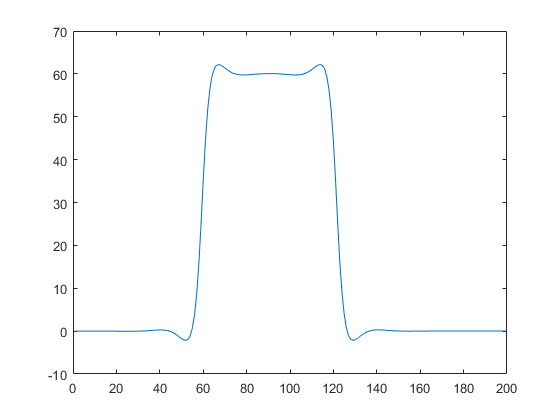

figure(2);
plot((1:200), y_1000(:, Iterations_1000));

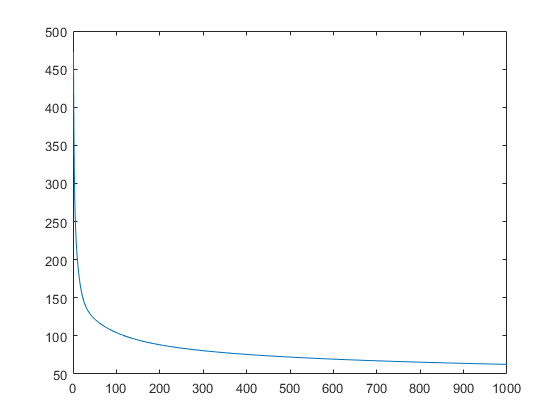

figure(3);
plot((1:Iterations_1000), error_norm_1000(:, 1));

%}

## 2000 Iterations

%
N = 200;

reference = zeros(N, 1);

G = zeros(N,N);
for row =  1:N 
    for col = 1:row
        G(row,col) = C*(A^(row-col))*B;
    end 
end

for i = 1:N
    if (i < 60) || (i > 121)
        reference(i, 1) = 0;
    else
        reference(i, 1) = 60;
    end
end

Iterations_2000 = 2000;

u_2000 = zeros(N, Iterations_2000+1);
e_2000 = zeros(N, Iterations_2000);
Y_2000 = zeros(1, Iterations_2000);
error_norm_2000 = zeros(Iterations_2000);
y_2000 = zeros(N, Iterations_2000);

for n = 1:Iterations_2000
    e_2000(:, n) = reference(:, 1) - G*u_2000(:, n);
    Y_2000(n) = ((norm(G'*e_2000(:, n)))^2)/(w + (norm(G*G'*e_2000(:, n)))^2);
    u_2000(:, n+1) = u_2000(:, n) + Y_2000(n)*G'*e_2000(:, n);
    error_norm_2000(n) = norm(e_2000(:, n));
    y_2000(:, n) = G*u_2000(:, n);
end

figure(1);
plot((1:200), reference);

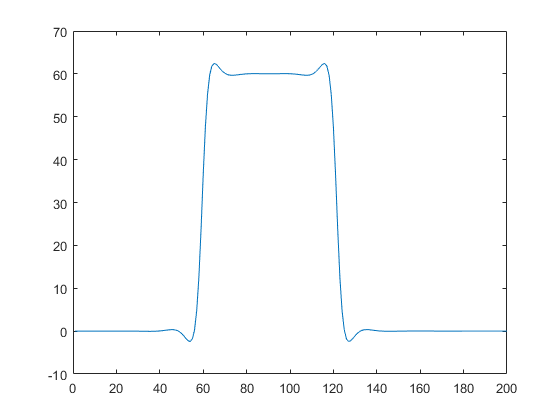

figure(2);
plot((1:200), y_2000(:, Iterations_2000));

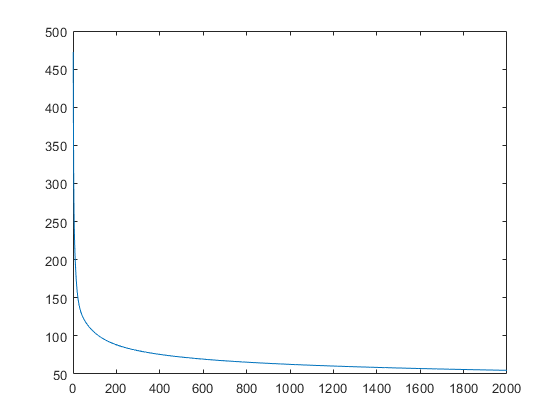

figure(3);
plot((1:Iterations_2000), error_norm_2000(:, 1));

%}

## Comparison

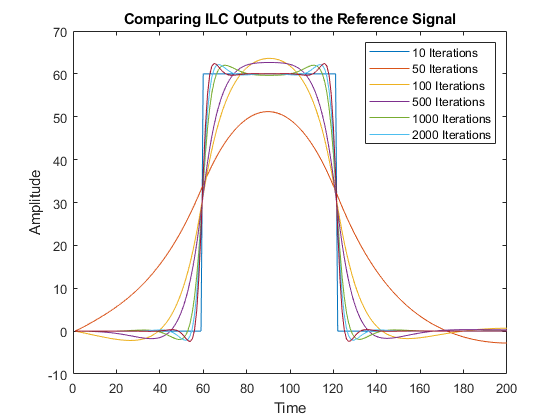

figure(1);
plot((1:200), reference);
hold on;
plot((1:200), y_10(:, Iterations_10));
hold on;
plot((1:200), y_50(:, Iterations_50));
hold on;
plot((1:200), y_100(:, Iterations_100));
hold on;
plot((1:200), y_500(:, Iterations_500));
hold on;
plot((1:200), y_1000(:, Iterations_1000));
hold on;
plot((1:200), y_2000(:, Iterations_2000));
hold on;
title("Comparing ILC Outputs to the Reference Signal");
xlabel("Time");
ylabel("Amplitude");
legend("10 Iterations", "50 Iterations", "100 Iterations", "500 Iterations", "1000 Iterations", "2000 Iterations");
hold off;

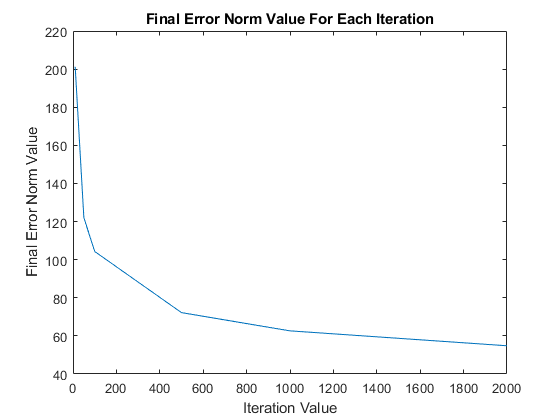


figure(2);
iteration_number_list_1_15 = [10, 50, 100, 500, 1000, 2000];
error_norm_final_list_1_15 = [error_norm_10(10, 1), error_norm_50(50, 1), error_norm_100(100, 1), error_norm_500(500, 1), error_norm_1000(1000, 1), error_norm_2000(2000, 1)];
plot(iteration_number_list_1_15, error_norm_final_list_1_15);
title("Final Error Norm Value For Each Iteration");
xlabel("Iteration Value");
ylabel("Final Error Norm Value");
hold off;